# Interface para todos os métodos

CHAMADA DE FUNÇÕES:

26/03/2021  Arménio Correia  armenioc@isec.pt

Trabalho realizado por:(23/04/2021)

        Diogo Silva - 2020138438 - a2020138438@isec.pt

        Hugo Ferreira - 2020128305 - 2020128305@isec.pt

        Rúben Mendes  - 2020138473 - a2020138473@isec.pt

clc
clear

syms y(t)

strF = input('f(t,y) = ','s');
f = @(t,y)eval(vectorize(strF));
disp('----- Métodos numéricos PVI ------ ');

----- Métodos numéricos PVI ------ 


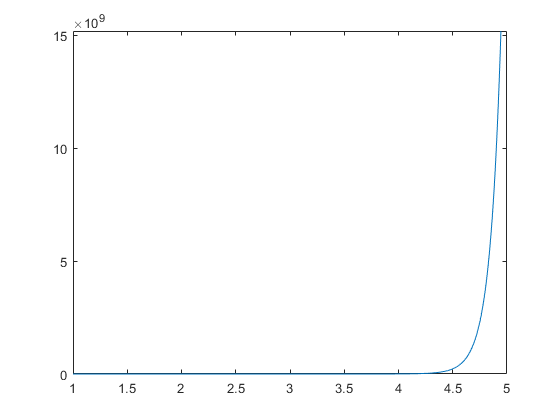

a  = str2num(input('a = ','s'));
b  = str2num(input('b = ','s'));
n  = str2num(input('n = ','s'));
y0 = str2num(input('y0 = ','s'));

yMEuler = MEuler(f,a,b,n,y0);
yEulerM = MeulerMelhorado(f,a,b,n,y0);
yRK2 = NRK2(f,a,b,n,y0);
yRK4 = NRK4(f,a,b,n,y0);
yODE23 = NODE23(f,a,b,n,y0);
yODE45 = NODE45(f,a,b,n,y0);
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroEuler = abs(yExata-yMEuler);
erroEulerM = abs(yExata-yEulerM);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
erroODE23 = abs(yExata-yODE23);
erroODE45 = abs(yExata-yODE45);
disp('----- Tabela de Valores ------ ');

----- Tabela de Valores ------ 


tabela = [t.',yExata.',yMEuler.',yEulerM.',yRK2.',yRK4.',yODE23.',yODE45.',erroEuler.',erroEulerM.',erroRK2.',erroRK4.',erroODE23.',erroODE45.'];
array2table(tabela,"VariableNames",{'t','Exata','MEuler','MEuler melhorado','RK2','RK4','ODE23','ODE45','Erro Euler','Erro Euler Melhorado','Erro RK2','Erro RK4','Erro ODE23','Erro ODE45'})

ans = 11×14 table
     t       Exata       MEuler    MEuler melhorado       RK2           RK4          ODE23         ODE45       Erro Euler    Erro Euler Melhorado     Erro RK2      Erro RK4     Erro ODE23    Erro ODE45
    ___    __________    ______    ________________    __________    __________    __________    __________    __________    ____________________    __________    __________    __________    __________

      1             1         1              1                  1             1             1        


disp('----- Gráfico de Soluções ------ ');

----- Gráfico de Soluções ------ 




disp('----- Euler ------ ');

----- Euler ------ 


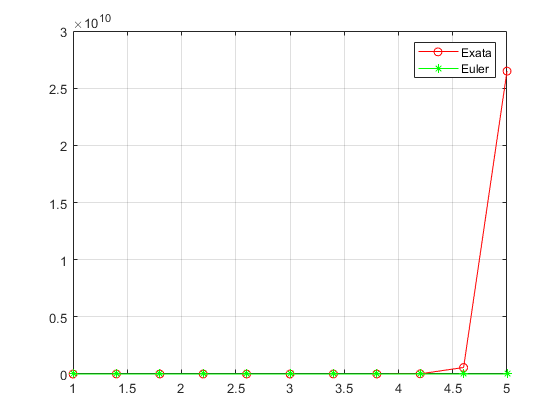

plot(t,yExata,"-ro")
hold on
plot(t,yMEuler,"-g*")
hold off
grid on
legend('Exata','Euler')


disp('----- Euler Melhorado ------ ');

----- Euler Melhorado ------ 


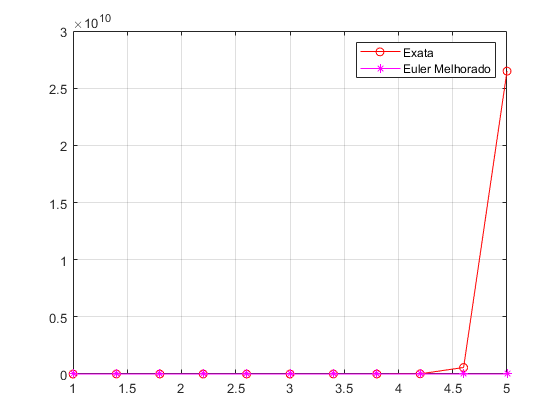

plot(t,yExata,"-ro")
hold on
plot(t,yEulerM,"-m*")
hold off
grid on
legend('Exata','Euler Melhorado')


disp('----- RK2 ------ ');

----- RK2 ------ 


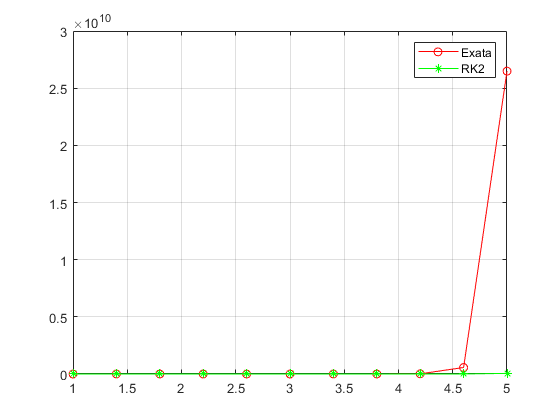

plot(t,yExata,"-ro")
hold on
plot(t,yRK2,"-g*")
hold off
grid on
legend('Exata','RK2')


disp('----- RK4 ------ ');

----- RK4 ------ 


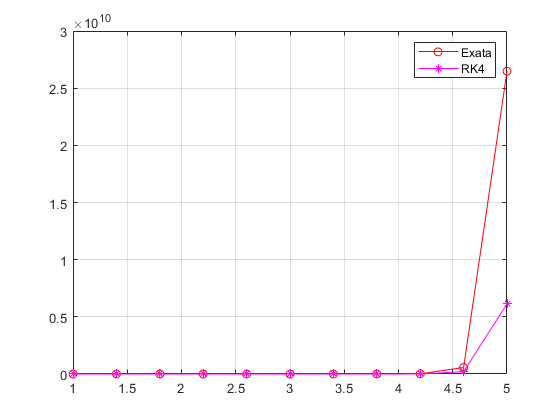

plot(t,yExata,"-ro")
hold on
plot(t,yRK4,"-m*")
hold off
grid on
legend('Exata','RK4')


disp('----- ODE23 ------ ');

----- ODE23 ------ 


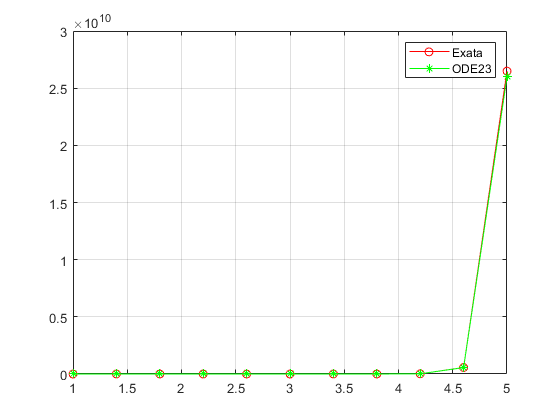

plot(t,yExata,"-ro")
hold on
plot(t,yODE23,"-g*")
hold off
grid on
legend('Exata','ODE23')


disp('----- ODE45 ------ ');

----- ODE45 ------ 


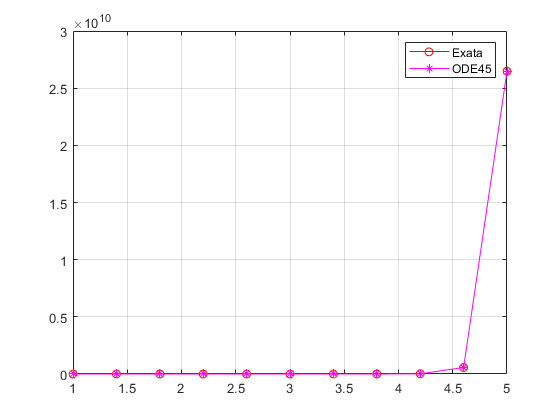

plot(t,yExata,"-ro")
hold on
plot(t,yODE45,"-m*")
hold off
grid on
legend('Exata','ODE45')